## Matlab Excercises: Naïve Bayes

[https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html](https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html)

Load Fisher's iris flowers dataset

load fisheriris
X = meas(:,3:4);
Y = species;
tabulate(Y)

       Value    Count   Percent
      setosa       50     33.33%
  versicolor       50     33.33%
   virginica       50     33.33%


Fit model

defaultMdl = fitcnb(X,Y,'ClassNames',{'setosa','versicolor','virginica'});

### Plot Gaussian contours

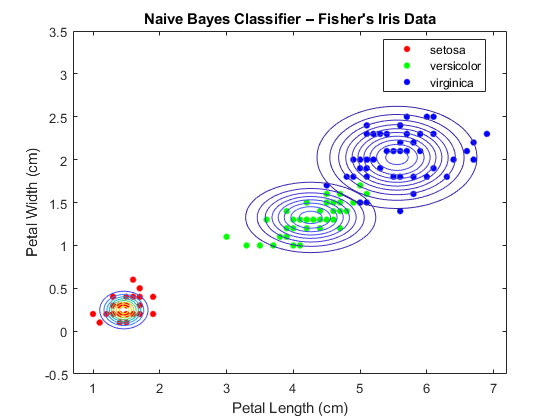

figure
gscatter(X(:,1),X(:,2),Y);
title('Naive Bayes Classifier -- Fisher''s Iris Data');
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');

h = gca;
cxlim = h.XLim;
cyLim = h.YLim;
hold on;
Params = cell2mat(defaultMdl.DistributionParameters);
Mu = Params(2*(1:3)-1,1:2); %extract the means
Sigma = zeros(2,2,3);
for j = 1:3
  Sigma(:,:,j) = diag(Params(2*j,:)).^2; % Diagonal covariance matrix
  xlim = Mu(j,1) + 4*[-1 1]*sqrt(Sigma(1,1,j));
  ylim = Mu(j,2) + 4*[-1 1]*sqrt(Sigma(2,2,j));
  f = @(x,y) arrayfun(@(x0,y0) mvnpdf([x0 y0],Mu(j,:),Sigma(:,:,j)),x,y);
  fcontour(f,[xlim,ylim]) % Draw contours for multivariate normal distribution
end
legend('setosa','versicolor','virginica'); % put here so that arrayfun legends for contours do not appear
hold off;

### Specifying Prior Probabilities


load fisheriris.mat
X = meas;
Y = species;
classNames = {'setosa','versicolor','virginica'}; % Class order
defaultMdl = fitcnb(X,Y,'ClassNames',{'setosa','versicolor','virginica'});
defaultMdl.Prior

ans =     0.3333    0.3333    0.3333



prior = [0.5 0.2 0.3];
priorMdl = fitcnb(X,Y,'ClassNames',classNames,'Prior',prior)

priorMdl =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {3×4 cell}


  Properties, Methods


priorMdl.Prior

ans =     0.5000    0.2000    0.3000



prior2 = [0.2 0.3 0.5];
priorMdl2 = fitcnb(X,Y,'ClassNames',classNames,'Prior',prior)

priorMdl2 =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {3×4 cell}


  Properties, Methods


Create Prior model with prior class distribution normalised (0.333 for each of the 3 parameters, just like the default)

NormalisedPriorMdl = priorMdl;
freqDist = cell2table(tabulate(Y));
NormalisedPriorMdl.Prior = freqDist{:,3}

NormalisedPriorMdl =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {3×4 cell}


  Properties, Methods


NormalisedPriorMdl.Prior

ans =     0.3333    0.3333    0.3333


Use 10 fold crossvalidation to estimate loss on each model

rng(1); % For reproducibility
defaultCVMdl = crossval(defaultMdl);
defaultLoss = kfoldLoss(defaultCVMdl);
priorCVMdl = crossval(priorMdl);
priorLoss = kfoldLoss(priorCVMdl);
priorCVMdl2 = crossval(priorMdl2);
priorLoss2 = kfoldLoss(priorCVMdl2);

fprintf("Default loss: %0.02f\nPrior loss  : %0.02f\nPrior2 loss : %0.02f\n", defaultLoss, priorLoss, priorLoss2);

Default loss: 0.05
Prior loss  : 0.03
Prior2  loss: 0.04


It's worth noticing that the prior probabilities affect the loss and how.

### Predictor Distributions

load fisheriris
X = meas;
Y = species;
Mdl1 = fitcnb(X,Y,...
    'ClassNames',{'setosa','versicolor','virginica'})

Mdl1 =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {3×4 cell}


  Properties, Methods


One 

disp(Mdl1.DistributionParameters);

    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}



disp(cell2mat(Mdl1.DistributionParameters));

    5.0060    3.4280    1.4620    0.2460
    0.3525    0.3791    0.1737    0.1054
    5.9360    2.7700    4.2600    1.3260
    0.5162    0.3138    0.4699    0.1978
    6.5880    2.9740    5.5520    2.0260
    0.6359    0.3225    0.5519    0.2747



4 predictors per class: columns

3 classes (rows of cells (2x1))

Each predictor cell holds mean (1,1) and standard deviation (1,2)

**The confusion matrix is evaluated below**

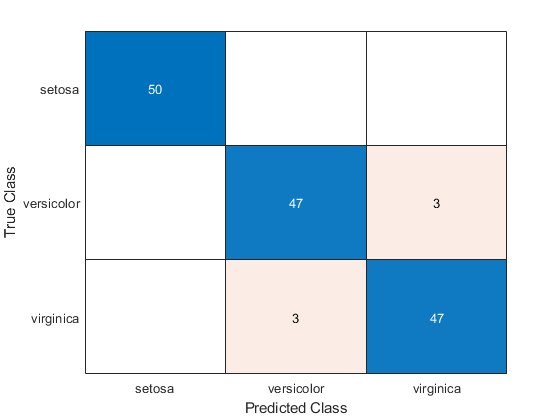

[predicted, score] = resubPredict(Mdl1);
confusionMat1 = confusionchart(Y, predicted);

tabulate(Y)

       Value    Count   Percent
      setosa       50     33.33%
  versicolor       50     33.33%
   virginica       50     33.33%


The confusion matrix shows in pink the number of examples that are incorrectly classified. Ie: 3 examples were predicted as versicolor but are really virginica.